%-------------ingenierias y tecnologias---------------------
%---------------ingenieria electronica----------------------
%--------------------Control 1------------------------------
%DISEÑO DE COMPENSADOR EN ATRASO METODO FRECUENCIAL
clc
clear all
disp('*DISEÑO DE COMPENSADOR EN ATRASO METODO FRECUENCIAL*')

*DISEÑO DE COMPENSADOR EN ATRASO METODO FRECUENCIAL*


s=tf('s');
G=input('FUNCION DE TRANSFERENCIA LAZO ABIERTO (s) : ');
n=input('¿ES UNA ESPECIFICACION DE EP(1), EV(2) o EA(3)?: ');
if n==1
    n1=input('MI VALE, QUE TE PIDEN EP(1) O KP(2): ');
    if n1==2
    kp=input('DIGITA EL VALOR DEL KP= ');
    kg=dcgain(G);
    K=kp/kg;
    end
    if n1==1
    ep=input('DIGITA EL VALOR DEL EP= ');
    kp=((1/ep)-1);
    kg=dcgain(G);
    K=kp/kg;
    end
end
if n==2
    n1=input('MI VALE, QUE TE PIDEN Ev(1) O Kv(2): ');
    if n1==2
    kv=input('DIGITA EL VALOR DEL KV= ');
    kg=dcgain(s*G);
    K=kv/kg;
    t=0:0.1:100;
    end
    if n1==1
    ev=input('DIGITA EL VALOR DEL EV= ');
    kv=((1/ev));
    kg=dcgain(G*s);
    K=kv/kg;
    t=0:0.1:100;
    end
end
if n==3
     n1=input('MI VALE, QUE TE PIDEN Ev(1) O Kv(2): ');
    if n1==2
    ka=input('DIGITA EL VALOR DEL KA= ');
    kg=dcgain(s^2*G);
    K=ka/kg;
    t=0:0.1:100;
    end
    if n1==1
    ea=input('DIGITA EL VALOR DEL EA= ');
    ka=((1/ea));
    kg=dcgain(s^2*G);
    K=ka/kg;
    t=0:0.1:100;
    end 
end
MFd=input('DIGITA MFd REQUERIDO= ');
teta=input('ANGULO DE CORRECCION [5° a 12°]= ');
fm = -180+MFd+teta 

fm = -134

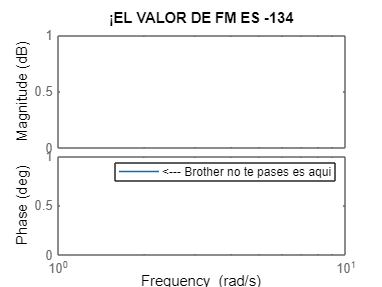

bode(G*K),title(['¡EL VALOR DE FM ES ',num2str(fm)]),legend('<--- Brother no te pases es aqui');

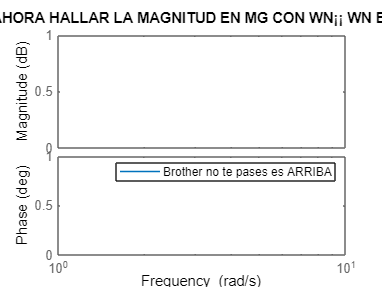

WN=input('DIGITA EL VALOR DEL WN= ');
z = 0.1*WN;
bode(G*K),title(['!AHORA HALLAR LA MAGNITUD EN MG CON WN¡¡ WN ES ',num2str(WN)]),legend('Brother no te pases es ARRIBA');

B=input('DIGITA EL VALOR QUE TE DIO LA MAGNITUD= ');
beta = 10^((B)/20)

beta = 1.9953e-07

T = 1/z;
p = 1/(beta*T);
Kc = K/beta;
C = zpk([-z],[-p],[Kc])

C =
 
  NaN
 
Static gain.



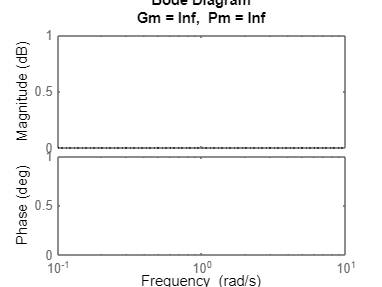

GB = G*C;
G11R = feedback(G,1);  
GBR = feedback(GB,1);
figure(1)
margin(G*C)

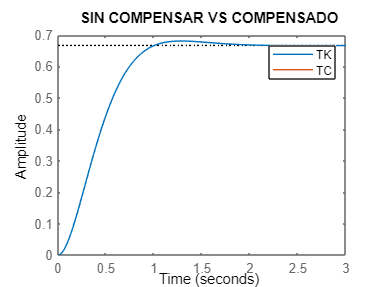

figure(2)
step(G11R,GBR),title('SIN COMPENSAR VS COMPENSADO'),legend('TK','TC');

Kp=dcgain(G*C)

Kp = NaN

Kv=dcgain(G*C*s)

Kv = NaN

Ka=dcgain(G*C*s*s)

Ka = NaN